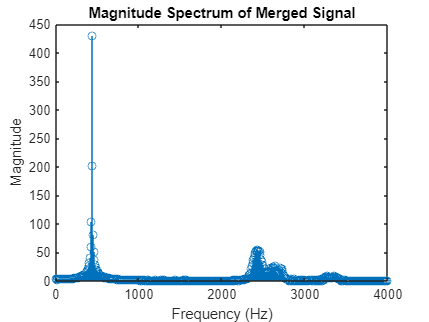

% Define the time vector for signal A
t = 0:1/8000:0.5;

% Create signal A
A = sin(2*pi*440*t);

% Load the chirp signal from chirp.mat
load chirp.mat; % Assuming 'y' is the chirp signal

% Convert 'y' from column to row vector if necessary
Z = y';

% Pad the shorter signal with zeros to make both signals the same length
if length(A) > length(Z)
    Z = [Z, zeros(1, length(A) - length(Z))];
elseif length(Z) > length(A)
    A = [A, zeros(1, length(Z) - length(A))];
end

% Add the two signals
mergedSignal = A + Z;
sound(mergedSignal, 8000);

% Define length of the FFT (nfft)
nfft = 1024;

% Compute the Fast Fourier Transform (FFT) of the merged signal
MergedX = fft(mergedSignal, nfft);

% Extract the first half of MergedX for positive frequencies
MergedX = MergedX(1:nfft/2+1);

% Calculate the magnitude of the FFT
mag_MergedX = abs(MergedX);

% Calculate the phase of the FFT
phase_MergedX = angle(MergedX);

% Frequency vector for plotting
f = (0:nfft/2)*8000/nfft;

% Plot the magnitude of the FFT
figure(1);
stem(f, mag_MergedX);
title('Magnitude Spectrum of Merged Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

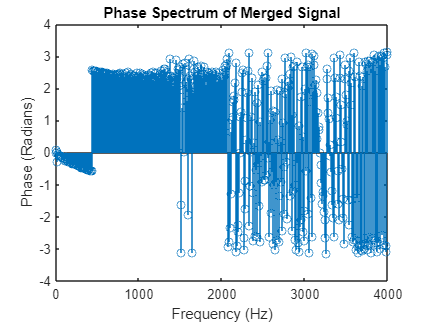


% Plot the phase of the FFT
figure(2);
stem(f, phase_MergedX);
title('Phase Spectrum of Merged Signal');
xlabel('Frequency (Hz)');
ylabel('Phase (Radians)');